error_benign =     0.6060    0.5413    0.5821    0.6824    0.7391    0.7108    0.7881    0.7164


optrank_b = 7

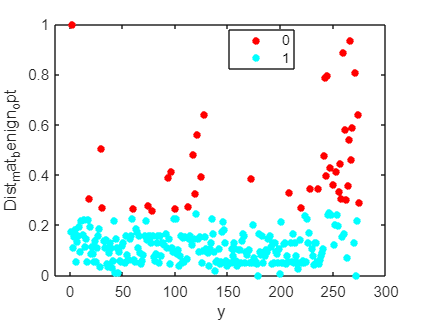

error_malignant =     0.0367    0.0225    0.1123    0.6135    0.1518    0.6233    0.2769    0.3809


optrank_m = 6

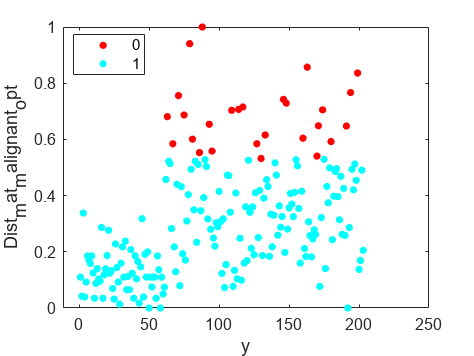

error_benign =     0.6272    0.7024    0.6107    0.6844    0.7606    0.4115    0.6373    0.2470


optrank_b = 5

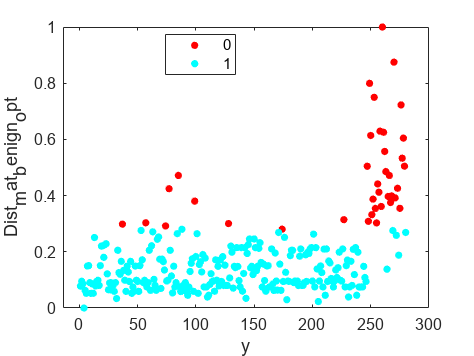

error_malignant =     0.0405    0.0173    0.0193    0.7038    0.2961    0.6945    0.5440    0.8471


optrank_m = 8

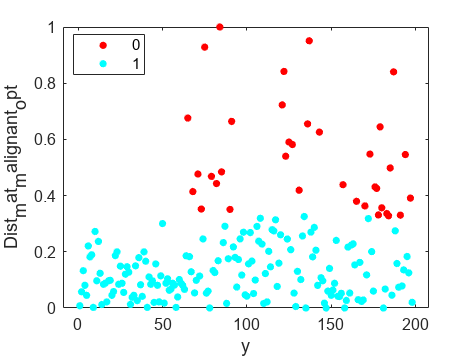

error_benign =     0.6820    0.6295    0.6408    0.8182    0.8881    0.5136    0.7462    1.1420


optrank_b = 8

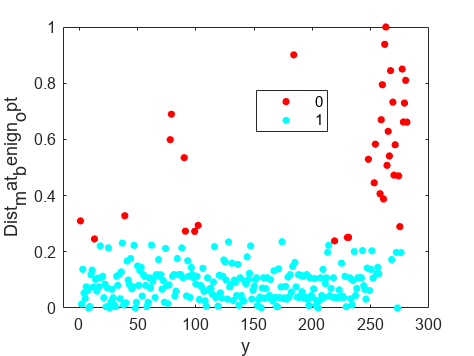

error_malignant =     1.3437    2.4165    0.4609    1.0943    0.4329    0.2141    0.2895    0.4790


optrank_m = 2

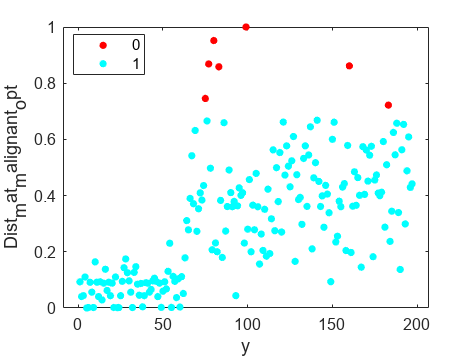

error_benign =     0.6342    0.6763    0.7669    0.9029    0.8901    1.0978    0.9345    0.9656


optrank_b = 6

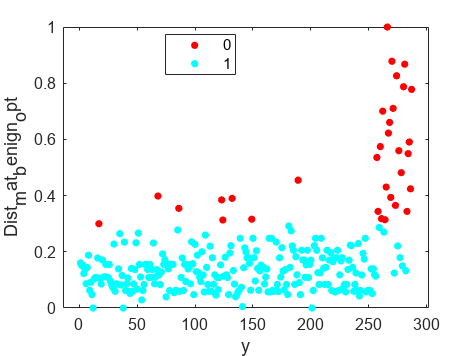

error_malignant =     0.5539    0.7791    0.8340    0.6221    0.1328    0.2345    0.3499    0.4763


optrank_m = 3

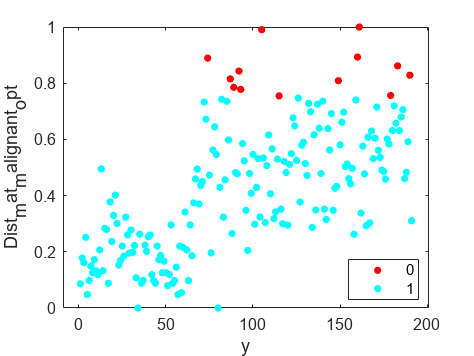

error_benign =     0.5929    0.6084    0.5792    0.6340    0.7427    0.7782    0.8014    0.3150


optrank_b = 7

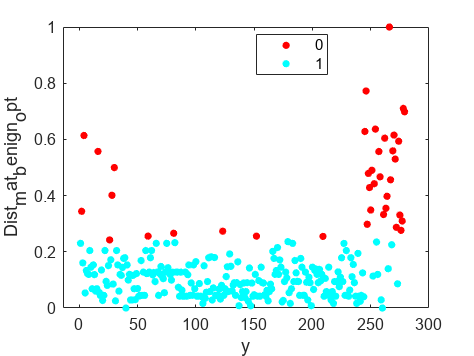

error_malignant =     1.0561    0.0632    0.1200    0.2636    0.1372    0.2812    0.3505    0.5265


optrank_m = 1

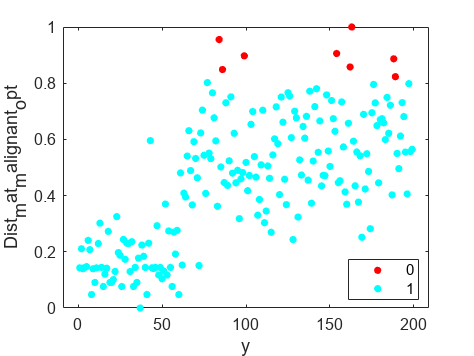

error_benign =     0.6443    0.6769    0.7370    0.6354    0.4752    0.4081    0.3865    0.3385


optrank_b = 3

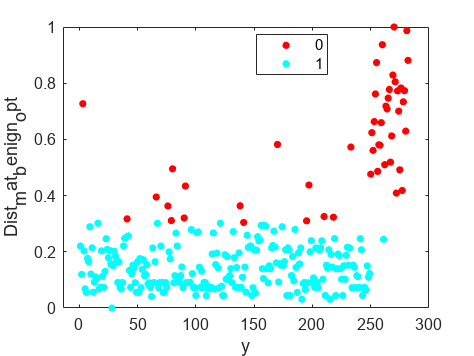

error_malignant =     1.0652    1.6350    0.6511    1.4229    0.1068    0.1909    0.2841    0.4269


optrank_m = 2

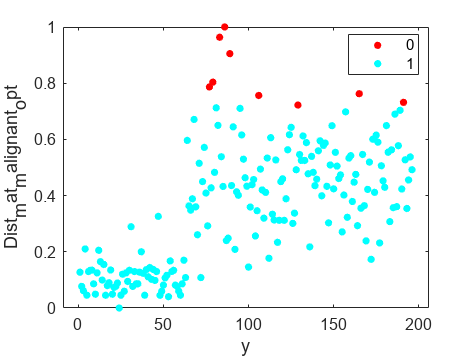

error_benign =     0.5658    0.5254    0.6285    0.7157    0.9848    0.6042    0.4091    0.5834


optrank_b = 5

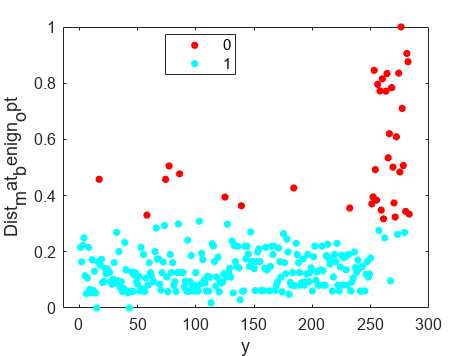

error_malignant =     1.1668    1.0972    1.2146    0.9011    1.6361    0.1960    0.4202    0.5441


optrank_m = 5

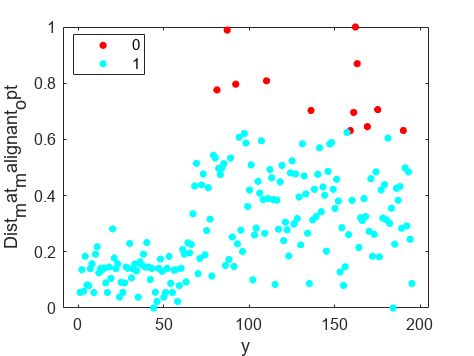

error_benign =     0.6165    0.6564    0.6394    0.7405    0.8849    0.7902    1.1466    0.2963


optrank_b = 7

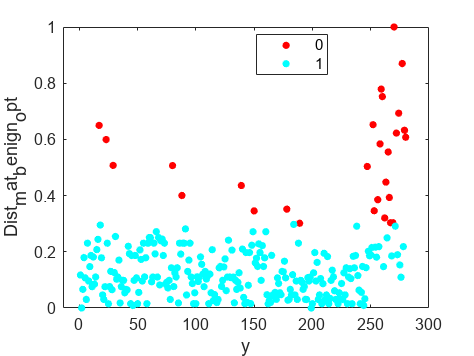

error_malignant =     4.2324    0.0769    0.0215    0.5039    0.2192    0.3104    0.2654    0.3597


optrank_m = 1

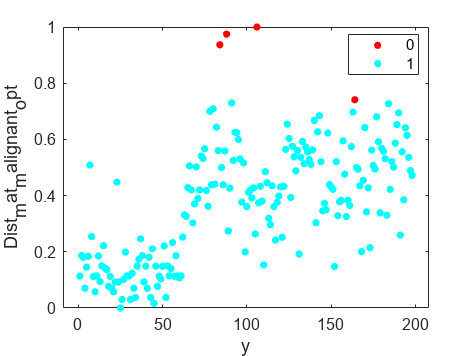

error_benign =     0.6183    0.6419    0.6486    0.7032    0.7935    0.9431    0.4675    2.0764


optrank_b = 8

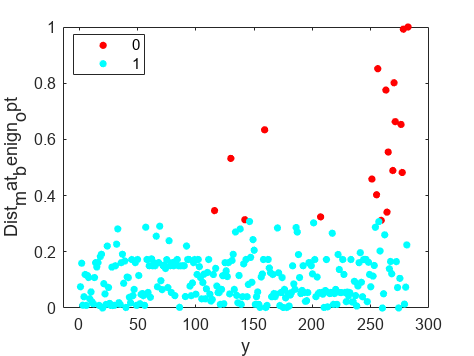

error_malignant =     1.2221    0.5616    1.5446    1.4159    0.6662    0.2199    0.3194    0.6956


optrank_m = 3

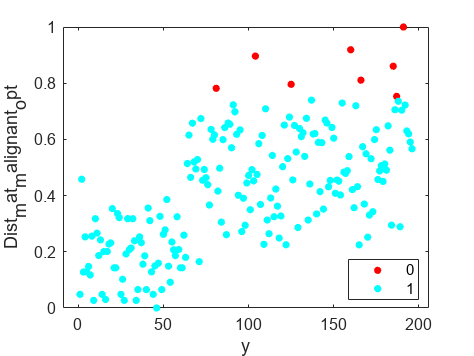

error_benign =     0.6486    0.6688    0.6573    0.7075    0.8160    0.5342    0.4529    0.4379


optrank_b = 5

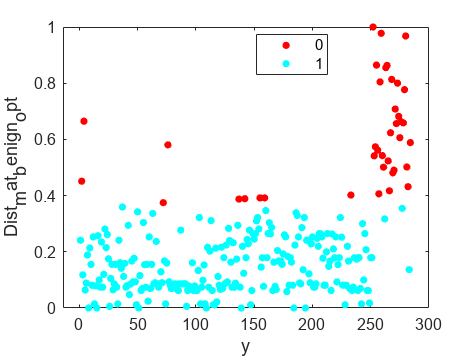

error_malignant =     0.0240    0.0083    0.0843    0.0447    1.3899    0.2900    0.7811    0.6279


optrank_m = 5

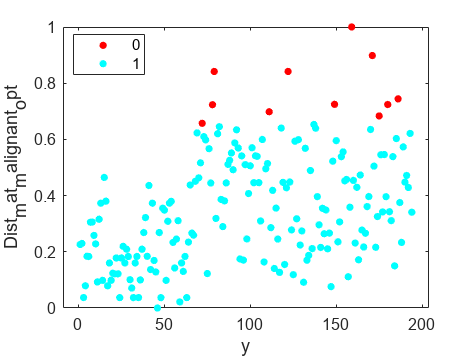

for j = [1,2,3,4,5,6,7,8,9,10]
    figure

    splitfolder=strcat('split',num2str(j));
    per =[20];%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('cell_sample_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        benign=File(File(:,10)==2,1:9);
        T_benign=benign.';
        malignant=File(File(:,10)==4,1:9);
        T_malignant=malignant.';

        folder_l1=strcat('ACE_dist_8optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3,4,5,6,7,8];

        error_benign = nan(size(ranks));
        numbenign=length(T_benign);
        Dist_mat_benign_array=nan(length(ranks),numbenign);
        threshold_rank_b=nan(size(ranks));
        elbow_indx_rank_b=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

            T_benign_temp=T_benign;
            Dist_mat_benign=[];


            BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
            for k = 1 : numbenign
                A=T_benign(:,k);
                Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_benign,[],"all");
            max_val=max(Dist_mat_benign,[],"all");
            Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
            Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


            Dist_mat_benign_array(i,:)=Dist_mat_benign;
            [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");


            [elbow_b_err_angle,elbow_indx_b]=knee_pt_angle((Dist_mat_benign_asc));

            error_benign(i)=elbow_b_err_angle;
            threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
            elbow_indx_rank_b(i)=elbow_indx_b;

% 
%             figure
%             plot((Dist_mat_benign_asc),'-s',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance Benign Asc for Rank",num2str(i)])
%             title(['Rank =',num2str(i) ])


        end

        
        error_benign

        [~,optrank_b]= max(error_benign)

        Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
        threshold_dist_b= threshold_rank_b(optrank_b);
        elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);

        ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
        ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);


        cluster_b=zeros(size(Dist_mat_benign_opt));
        cluster_b(ind_I_b)=1;
        figure
        y= 1:1:length(benign);
        numGroups = length(unique(cluster_b));
        gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))
% 
%         figure
%         plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b_opt),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("index")
%         ylabel(["Distance Benign Asc for opt rank" ,num2str(optrank_b)])
%         title(['Rank opt for Benign =',num2str(optrank_b),"Split=",num2str(j)])
%         ind_O_b;


        T_benign_temp(:,ind_O_b)=[];
        length(T_benign_temp);

        Final_benign=T_benign_temp';
        Final_benign(:,10)=2;

    end
    %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    nummalignant=length(T_malignant);
    error_malignant=nan(size(ranks));
    Dist_mat_mal_array=nan(length(ranks),nummalignant);
    threshold_rank_m=nan(size(ranks));
    elbow_rank_m=nan(size(ranks));


    for i=ranks
        %fprintf("Rank is %i \n", i) %i);

        T_malignant_temp=T_malignant;
        Dist_mat_malignant=[];

        BF_malignant=l1pca_BF(T_malignant,i,1,10,10,'');
        for k = 1 : nummalignant
            A=T_malignant(:,k);
            Dist_mat_malignant(k)=norm((A-(BF_malignant*BF_malignant.'*A)),1);
            k;
        end

        Dist_mat_malignant;
        min_val=min(Dist_mat_malignant,[],"all");
        max_val=max(Dist_mat_malignant,[],"all");
        Dist_mat_malignant= Dist_mat_malignant -min_val;%]/[max_val-min_val]
        Dist_mat_malignant=Dist_mat_malignant /(max_val-min_val);
        Dist_mat_mal_array(i,:)=Dist_mat_malignant;

        [Dist_mat_malignant_asc,Indx_m]=sort(Dist_mat_malignant,"ascend");


        [elbow_m_err_angle,elbow_indx_m]=knee_pt_angle((Dist_mat_malignant_asc));

        error_malignant(i)=elbow_m_err_angle;
        threshold_rank_m(i)=Dist_mat_malignant_asc(elbow_indx_m);
        elbow_rank_m(i)=elbow_indx_m;

%         figure
%         plot((Dist_mat_malignant_asc),'-*',"MarkerIndices",(elbow_indx_m),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("Index")
%         ylabel("Distance Malignant Asc")
%         title(["Rank =", num2str(i)])


    end
    error_malignant
    [~,optrank_m]= max(error_malignant)

    Dist_mat_malignant_opt=Dist_mat_mal_array(optrank_m,:);
    threshold_dist_m= threshold_rank_m(optrank_m);
    elbow_indx_m_opt=elbow_rank_m(optrank_m);

    ind_O_m=find(Dist_mat_malignant_opt>threshold_dist_m);
    ind_I_m=find(Dist_mat_malignant_opt<=threshold_dist_m);

    cluster_m=zeros(size(Dist_mat_malignant_opt));
    cluster_m(ind_I_m)=1;

    figure
    y= 1:1:length(malignant);
    numGroups = length(unique(cluster_m));
    gscatter(y,Dist_mat_malignant_opt,cluster_m,hsv(numGroups))

%     figure
%     plot(sort(Dist_mat_malignant_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_m_opt),'MarkerFaceColor','red','MarkerSize',10 )
%     xlabel("Index")
%     ylabel("Distance Malignant Asc for opt rank")
%     title(["Opt Rank for Malignant=",num2str(optrank_m),"Split=",num2str(j)])

    ind_O_m;


    T_malignant_temp(:,ind_O_m)=[];
    length(T_malignant_temp);

    Final_malignant=T_malignant_temp';
    Final_malignant(:,10)=4;


    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
    cd (splitfolder)
    cd (folder)

    cd (folder_l1)

    L1pca_file=(horzcat(Final_benign.',Final_malignant.')).';

    L1pca_file = array2table(L1pca_file);
    L1pca_file.Properties.VariableNames(1:10)=  {'Clump','UnifSize','UnifShape','MargAdh','SingEpiSize','BareNuc','BlandChrom','NormNucl','Mit','Class'};
    filel1pca=strcat('cell_sample_misclass_per',num2str(percent),'_ACE_l1pca.csv');
    writetable(L1pca_file,filel1pca);

end